# Задание 1

y_0_arr = [ 1 1 1 0.05 0.05 0 ];
dot_y_0_arr = [ 0 0 0 0 0 0.1 ];
lambda_1_arr = [ -4.5 -3.7+5i 29i 0.7+5i 4.5 -2.8 ];
lambda_2_arr = [ -5.5 -3.7-5i -29i 0.7-5i 5.5 2.8 ];

Выведем общую формулу для вычисления $a_0, a_1$:

Характеристическое уравнение: $\lambda^2+a_1\lambda+a_0=0$

Получим систему:


$$\begin{cases}
a_1=-\lambda_1-\lambda_2\\
a_0=\lambda_1\cdot\lambda_2
\end{cases}$$


Вычислим коэффициеты:

a_0_arr = zeros(1, 6);
a_1_arr = zeros(1, 6);

for k = 1:6
    a_1_arr(k) = - lambda_1_arr(k) - lambda_2_arr(k);
    a_0_arr(k) = lambda_1_arr(k) * lambda_2_arr(k);
end
fprintf('№  a_1\t\t a_0\n');

№  a_1		 a_0


for k = 1:6
    fprintf('%1i %7.3f\t%7.3f\n', ...
        k, a_1_arr(k), a_0_arr(k));
end

1  10.000	 24.750
2   7.400	 38.690
3   0.000	841.000
4  -1.400	 25.490
5 -10.000	 24.750
6   0.000	 -7.840


Получаем:

`№  a_1		 a_0`

`1  10.000	 24.750`

`2   7.400	 38.690`

`3   0.000	841.000`

`4  -1.400	 25.490`

`5 -10.000	 24.750`

`6   0.000	 -7.840`

`Перепишем наше ДУ в более удобном виде для построения схемы:`


$$p^2y+a_1py+a_0y=a_0u\Rightarrow
y=-\frac{1}{p}(a_1y+\frac{1}{p}a_0(y-u))
$$


Выразим начальные условия для интеграторов:

1. $y(0)=\frac{1}{p}(-a_1y-\frac{1}{p}a_0(y-u))\Rightarrow $для второго интегратора начальное условие $y(0)
$.

2. $py=(-a_1y-\frac{1}{p}a_0(y-u))=0\Rightarrow\frac{1}{p}a_0(y-u)=-py-a_1y\Rightarrow$для первого интегратора начальное условие $-\dot{y}(0)-a_1y(0)$.

Найдём аналитическое выражение для свободной составляющей движения системы $y_{\text{св}}(t)$ для каждого варианта:

1. $\begin{cases}
y_{св}(t)=C_1e^{-4.5t}+C_2e^{-5.5t}\\
y(0)=1 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_1+C_2=1\\
 -4.5C_1-5.5C_2=0
\end{cases}\Rightarrow
\begin{cases}
C_1=5.5\\
C_2=-4.5
\end{cases}\\
y_{св}(t)=5.5e^{-4.5t}-4.5e^{-5.5t}$

2. $\[
\begin{cases}
y_{\text{св}}(t)=e^{-3.7t}(C_1\sin(5t)+C_2\cos(5t))\\
y(0)=1 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_2 = 1 \\
-3.7C_2 + 5C_1 = 0
\end{cases}\Rightarrow
\begin{cases}
C_1 = 0.74 \\
C_2 = 1
\end{cases}
\]
\[
y_{\text{св}}(t)=e^{-3.7t}(0.74\sin(5t)+\cos(5t))
\]$

3. $\begin{cases}
y_{св}(t)=C_1\sin(29t)+C_2\cos(29t)\\
y(0)=1 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_2 = 1 \\
29C_1 = 0
\end{cases}\Rightarrow
\begin{cases}
C_1 = 0 \\
C_2 = 1
\end{cases}\\
y_{\text{св}}(t)=\cos(29t)$

4. $\begin{cases}
y_{св}(t)=e^{0.7t}(C_1\sin(5t)+C_2\cos(5))\\
y(0)=0.05 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_2 = 0.05 \\
0.7C_2 + 5C_1 = 0
\end{cases}\Rightarrow
\begin{cases}
C_1 = -0.007 \\
C_2 = 0.05
\end{cases}\\
y_{\text{св}}(t)=e^{0.7t}(-0.007\sin(5t)+0.05\cos(5t))$

5. $\begin{cases}
y_{св}(t)=C_1e^{5.5t}+C_2e^{4.5t}\\
y(0)=0.05 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_1 + C_2 = 0.05 \\
5.5C_1 + 4.5C_2 = 0
\end{cases}\Rightarrow
\begin{cases}
C_1 = -0.225 \\
C_2 = 0.275
\end{cases}\\
y_{\text{св}}(t)=-0.225e^{5.5t}+0.275e^{4.5t}$

6. $\begin{cases}
y_{св}(t)=C_1e^{2.8t}+C_2e^{-2.8t}\\
y(0)=0 \\
\dot{y}(0)=0.1
\end{cases}\Rightarrow
\begin{cases}
C_1 + C_2 = 0 \\
2.8C_1 - 2.8C_2 = 0.1
\end{cases}\Rightarrow
\begin{cases}
C_1 = 0.017857 \\
C_2 = -0.017857
\end{cases}\\
y_{\text{св}}(t)=\frac{1}{56}e^{2.8t}-\frac{1}{56}e^{-2.8t}$

Видим, что для всех систем результаты моделирования и аналитического расчёта совпали.

Проанализируем результаты на основе моделирования и корневого критерия:

1. **Моделирование: **график функции быстро уходит в ноль, похоже на ассимптотически устойчивую систему.

   **Корневой критерий:** корни $\lambda_1=-4.5,\quad\lambda_2=-5.5$, $Re(\lambda_i)<0\Rightarrow$ система действительно ассимптотически устойчива.

2. **Моделирование: **график уходит в ноль, хотя в начале наблюдается небольшая осцилляция, похоже на ассимптотическую устойчивость.

   **Корневой критерий:** корни $\lambda_{1,2}=-3.7\pm5i
$, $Re(\lambda_i)<0\Rightarrow$ система ассимптотически устойчива.

3.  **Моделирование: **тут мы имеем дело с обыкновенным синусом, похоже на устойчивость, но не ассимптотическую.

   **Корневой критерий:** корни $\lambda_{1,2}=\pm29i
$, $Re(\lambda_i)=0$ + не кратные корни $\Rightarrow$ граница устойчивости.

4.  **Моделирование: **система похоже на неустойчивую, видим колебания с увеличивающейся амплитудой со временем.

   **Корневой критерий:** корни $\lambda_{1,2}=0.7\pm5i$, $Re(\lambda_i)>0\Rightarrow$ система неустойчива.

5.  **Моделирование: **отрицательно растущая экспонента, система похожа не неустойчивую.

   **Корневой критерий:** корни $\lambda_1=4.5,\quad\lambda_2=5.5$, $Re(\lambda_i)>0\Rightarrow$ система неустойчива.

6.  **Моделирование: **график экспоненциальный, видна неустойчивость системы.

   **Корневой критерий:** корни $\lambda_{1,2}=\pm2.8$, есть один корень с $Re(\lambda)>0$ - этого достаточно, чтобы сделать вывод о неустойчивости системы.

**Выводы: **графики систем в нашем случае получились довольно наглядными, благодаря чему получилось визуально на основе моделирования оценить устойчивость, и данная оценка совпала со строгой проверкой при помощи корневого критерия. Результаты моделирования при помощи построения структурной схемы в симулинке совпали с аналитическими выводами формул. Коэффициенты $a$ довольно просто получилось найти при помощи характеристического уравнения для ДУ.

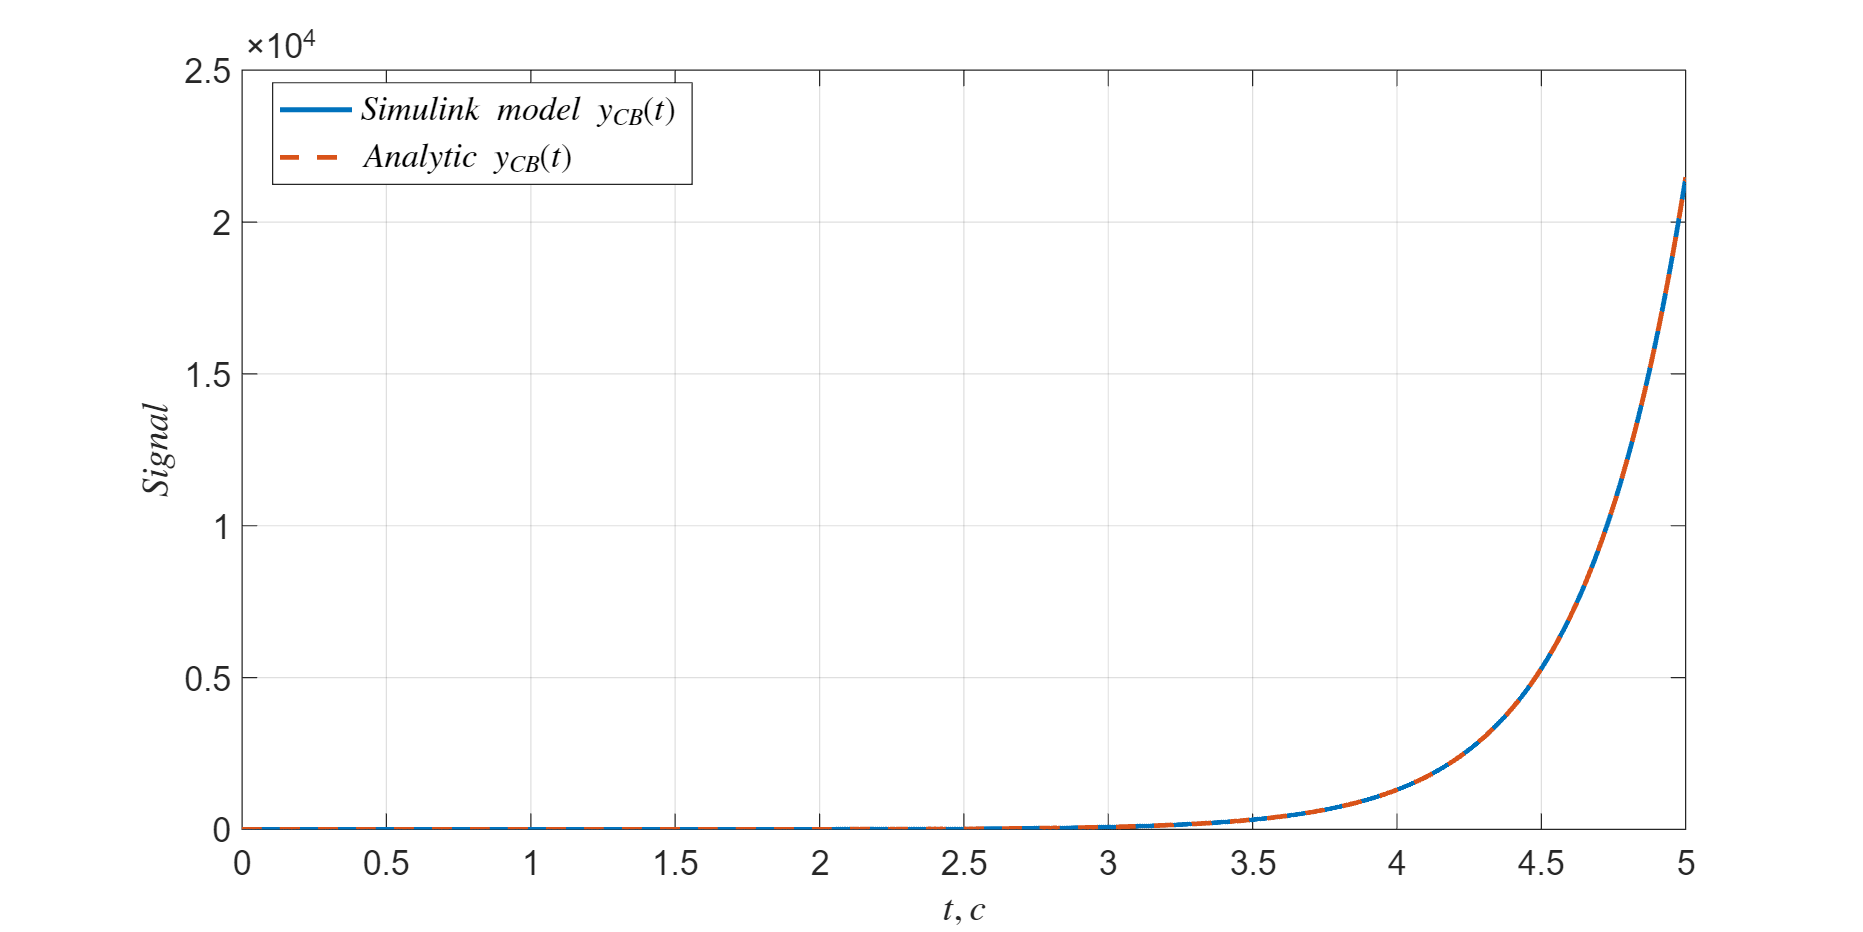

y_fm_array = {@y_fm_1, @y_fm_2, @y_fm_3, @y_fm_4, @y_fm_5, @y_fm_6};
simtime = 5;
time_interval = linspace(0, simtime, 10000);

for k=1:6
    y = y_fm_array{k}(time_interval);
    dot_y_0 = dot_y_0_arr(k);
    y_0 = y_0_arr(k);
    a_0 = a_0_arr(k);
    a_1 = a_1_arr(k);

    plot_1 = sim("lab_2_1.slx", simtime);
    plot(plot_1.y.Time, plot_1.y.Data, LineWidth=2, LineStyle="-");
    hold on;
    plot(time_interval, y, LineWidth=2, LineStyle="--");
    
    grid on;
    legend("$Simulink\ model\ y_{CB}(t)$", "$Analytic\ y_{CB}(t)$", Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$Signal$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_%d.png', k);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

# Задание 2

Определим постоянные $T$:


$$\lambda_1=-4.5,\quad T_1\cdot(-4.5)+1=0\Rightarrow T_1=\frac{2}{9}\\
\lambda_2=-5.5,\quad T_2\cdot(-5.5)+1=0\Rightarrow T_2=\frac{2}{11}$$


Определим аналитически границу устойчивости. Будем опираться на критерий Гурвица


$$y=\frac{1}{p}\left( \frac{K}{(T_1p+1)(T_2p+1)}(g-y) \right),\quad
py(T_1p+1)(T_2p+1)+Ky=Kg,\\
T_1T_2\dddot{y}+(T_1+T_2)\ddot{y}+\dot{y}+Ky=Kg;$$


Составим матрицу Гурвица:


$$\pmatrix{
T_1+T_2 & K & 0 \cr
T_1T_2 & 1 & 0 \cr
0 & T_1+T_2 & K
}$$


Выпишем выражения для ведущих угловых миноров матрицы и условия ассимптотической устойчивости:


$$\Delta_1=T_1+T_2,>0\quad \Delta_2=T_1+T_2-KT_1T_2>0,\quad \Delta_3=K\cdot\Delta_2=K(T_1+T_2-KT_1T_2)>0
$$
    

Зафиксируем $T_2=\frac{2}{11}$:


$$\begin{cases}
T_1>-\frac{2}{11}\\
K<\frac{11}{2}+\frac{1}{T_1}\\
K>0
\end{cases}\Rightarrow
\begin{cases}
K<\frac{11}{2}+\frac{1}{T_1}\\
K>0
\end{cases}$$


Соответственно, область ассимптотической устойчивость ограничена прямыми $K=0,\quad T_1=0$ и ветвью гиперболы $K<\frac{11}{2}+\frac{1}{T_1$ в 1-м квадранте.

Визуализируем (см. рис. ...), граница устойчивости выделена зелёным цветом.

Зафиксируем $T_1=\frac{2}{9}$:


$$\begin{cases}
T_2>-\frac{2}{9}\\
K<\frac{9}{2}+\frac{1}{T_2}\\
K>0
\end{cases}\Rightarrow
\begin{cases}
K<\frac{9}{2}+\frac{1}{T_2}\\
K>0
\end{cases}$$


Соответственно, область ассимптотической устойчивость ограничена прямыми $K=0,\quad T_2=0$ и ветвью гиперболы $K<\frac{9}{2}+\frac{1}{T_2}$ в 1-м квадранте.

Визуализируем (см. рис. ...), граница устойчивости выделена зелёным цветом.

Зададимся 3-мя наборами параметров $K, T_1, T_2$:

- Ассимптотическая устойчивость: $K=3,\quad T_1=17, \quad T_2=\frac{2}{9}$

- Система на границе устойчивости: $K=0.7,\quad T_1=2, \quad T_2=5$

- Неустойчивая система: $K=-1,\quad T_1=-3, \quad T_2=4$

Видим, что в случае ассимптотической устойчивости решение уравнения сходится к входному воздействию $g(t)=1$ - как и должно быть по теореме Ляпунова об ассимптотической устойчивости $\lim_{t\rightarrow\infty}||y(t)-g(t)||=0$.  График представляет собой затухающие колебания.

При границе устойчивости видим синусоидальный график.

В случае неустойчивой системы у на образуются расходящиеся колебания.

**Выводы:**

В данном задании мы научились работать с заданной структурной схемой, доставать оттуда нужные нам параметры. Использованный критерий Гурвица для данной задачи был весьма удобен, аналитические расчёты получились короткими и эффективными. С помощью него мы нашли области ассимптотической устойчивости системы при варьированных $T_i$, границу устойчивости и области неустойчивости системы. Также было выполнено моделирование при разлтичных комбинациях параметров для различных случаев устойчивости. Наш график выхода представил собой колебания, в зависимости от устойчивости системы, затухающие, не меняющие амплитуды или нарастающие. Результаты сошлись с аналитическими расчётами.

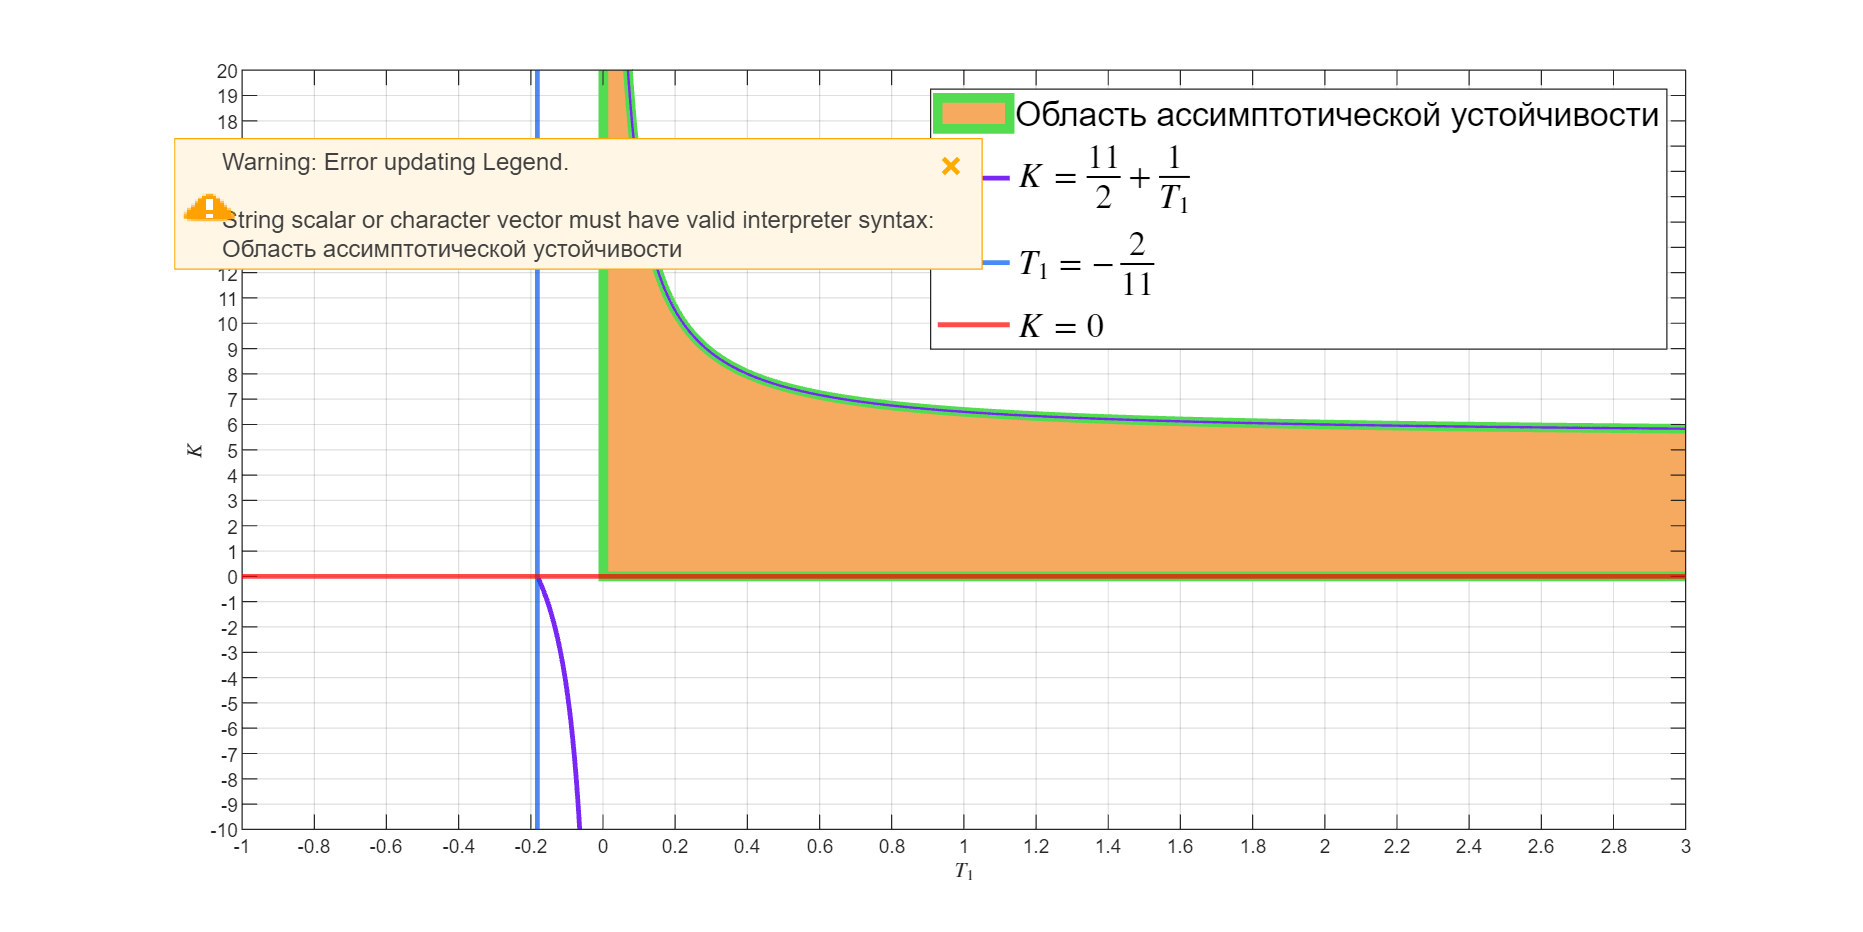

time_interval_T1 = linspace(-1, 4, 1000);

T1_masked = time_interval_T1(time_interval_T1 > -2/11);
line_2 = 5.5 + 1 ./ T1_masked;

figure;

positive_mask = T1_masked > 0;
T1_positive = T1_masked(positive_mask);
line_2_positive = line_2(positive_mask);
fill([T1_positive, fliplr(T1_positive)], [line_2_positive, zeros(size(line_2_positive))], ...
     [245, 170, 95]./255, EdgeColor='#53DB51', LineWidth=4, DisplayName='Область ассимптотической устойчивости');

xline(-2/11, LineWidth=2, LineStyle="-", color="#0057ED", DisplayName="$T_1=-\frac{2}{11}$");
hold on;

negative_mask = T1_masked < 0;
positive_mask = T1_masked > 0;
plot(T1_masked(negative_mask), line_2(negative_mask), LineWidth=2, LineStyle="-", color="#7927F5", DisplayName="$K=\frac{11}{2}+\frac{1}{T_1}$");
plot(T1_masked(positive_mask), line_2(positive_mask), LineWidth=1, LineStyle="-", color="#7927F5", HandleVisibility='off');

hold on;
yline(0, LineWidth=2, LineStyle="-", color="red", DisplayName="$K=0$");

grid on;
legend(Location="northeast", FontSize=14, Interpreter="latex");
xlabel("$T_1$", Interpreter="latex");
ylabel("$K$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);
xlim([-1, 3]);
ylim([-10, 20]);
xticks(-1:0.2:3);
yticks(-10:1:20);
set(gca, 'FontSize', 8);

hold off;
exportgraphics(gcf, 'images/plot_2_T2_fix.png', 'Resolution', 200)

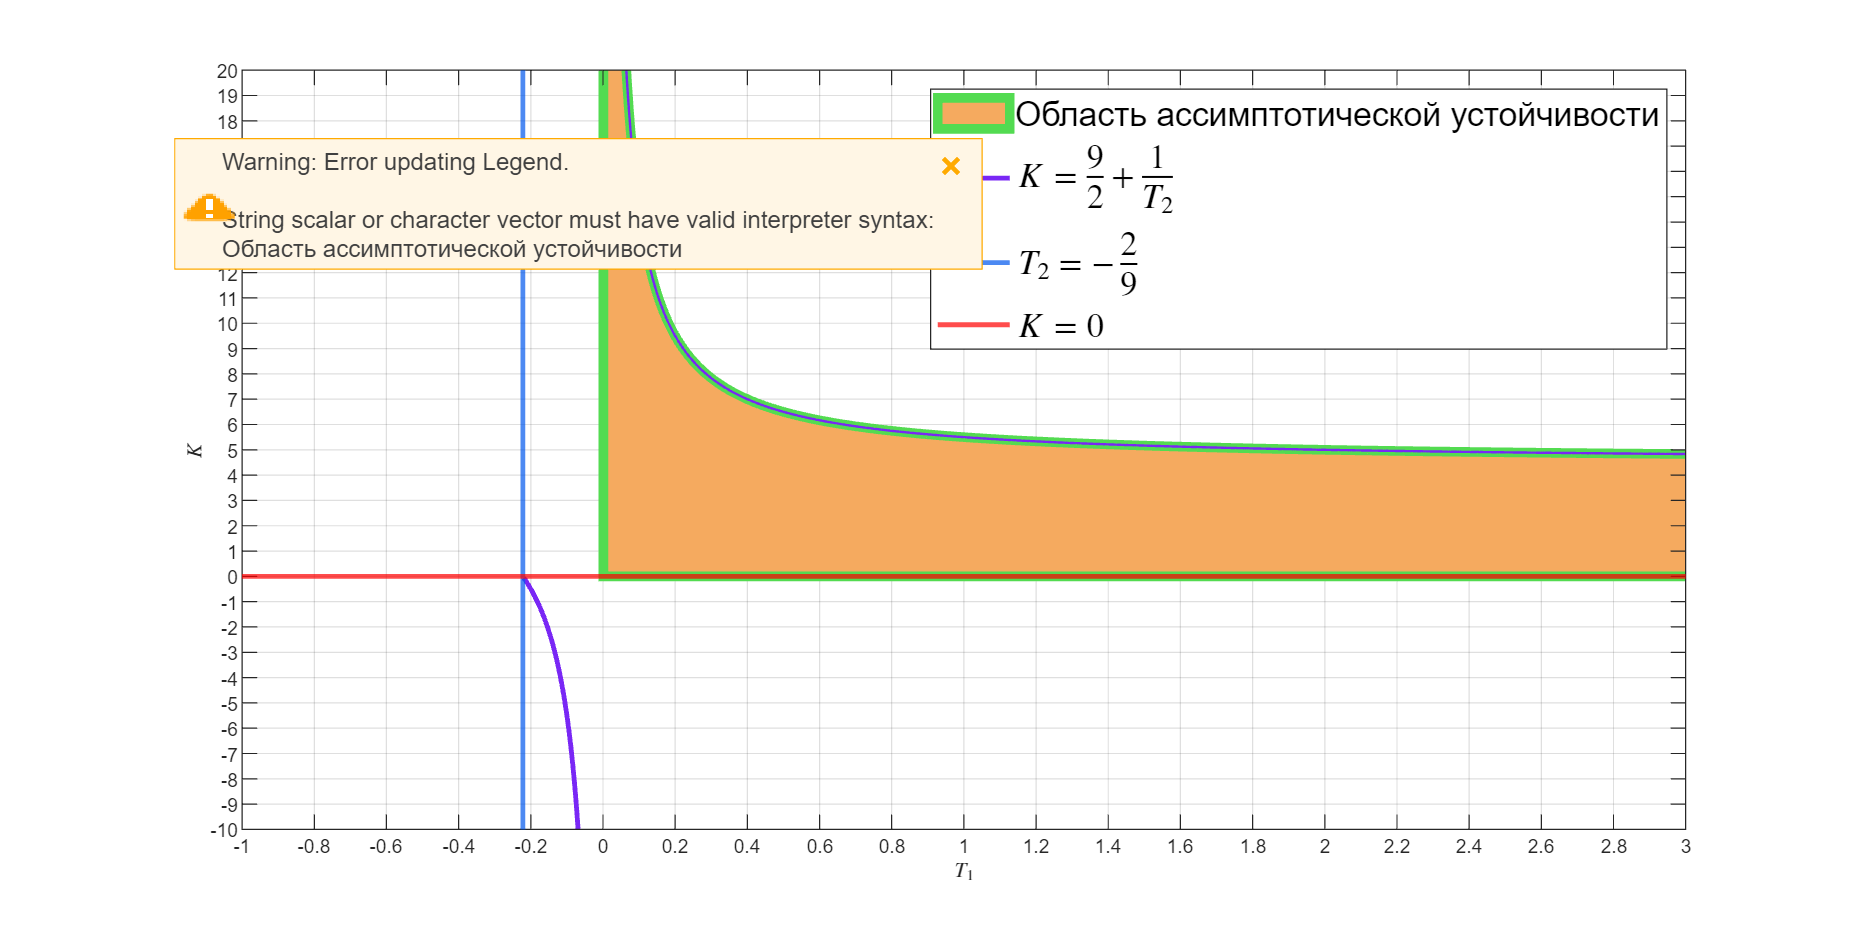

time_interval_T2 = linspace(-1, 4, 1000);

T2_masked = time_interval_T2(time_interval_T2 > -2/9);
line_2 = 4.5 + 1 ./ T2_masked;

figure;

positive_mask = T2_masked > 0;
T2_positive = T2_masked(positive_mask);
line_2_positive = line_2(positive_mask);
fill([T2_positive, fliplr(T2_positive)], [line_2_positive, zeros(size(line_2_positive))], ...
     [245, 170, 95]./255, EdgeColor='#53DB51', LineWidth=4, DisplayName='Область ассимптотической устойчивости');

xline(-2/9, LineWidth=2, LineStyle="-", color="#0057ED", DisplayName="$T_2=-\frac{2}{9}$");
hold on;

negative_mask = T2_masked < 0;
positive_mask = T2_masked > 0;
plot(T2_masked(negative_mask), line_2(negative_mask), LineWidth=2, LineStyle="-", color="#7927F5", DisplayName="$K=\frac{9}{2}+\frac{1}{T_2}$");
plot(T2_masked(positive_mask), line_2(positive_mask), LineWidth=1, LineStyle="-", color="#7927F5", HandleVisibility='off');

hold on;
yline(0, LineWidth=2, LineStyle="-", color="red", DisplayName="$K=0$");

grid on;
legend(Location="northeast", FontSize=14, Interpreter="latex");
xlabel("$T_1$", Interpreter="latex");
ylabel("$K$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);
xlim([-1, 3]);
ylim([-10, 20]);
xticks(-1:0.2:3);
yticks(-10:1:20); 
set(gca, 'FontSize', 8);

hold off;
exportgraphics(gcf, 'images/plot_2_T1_fix.png', 'Resolution', 200)

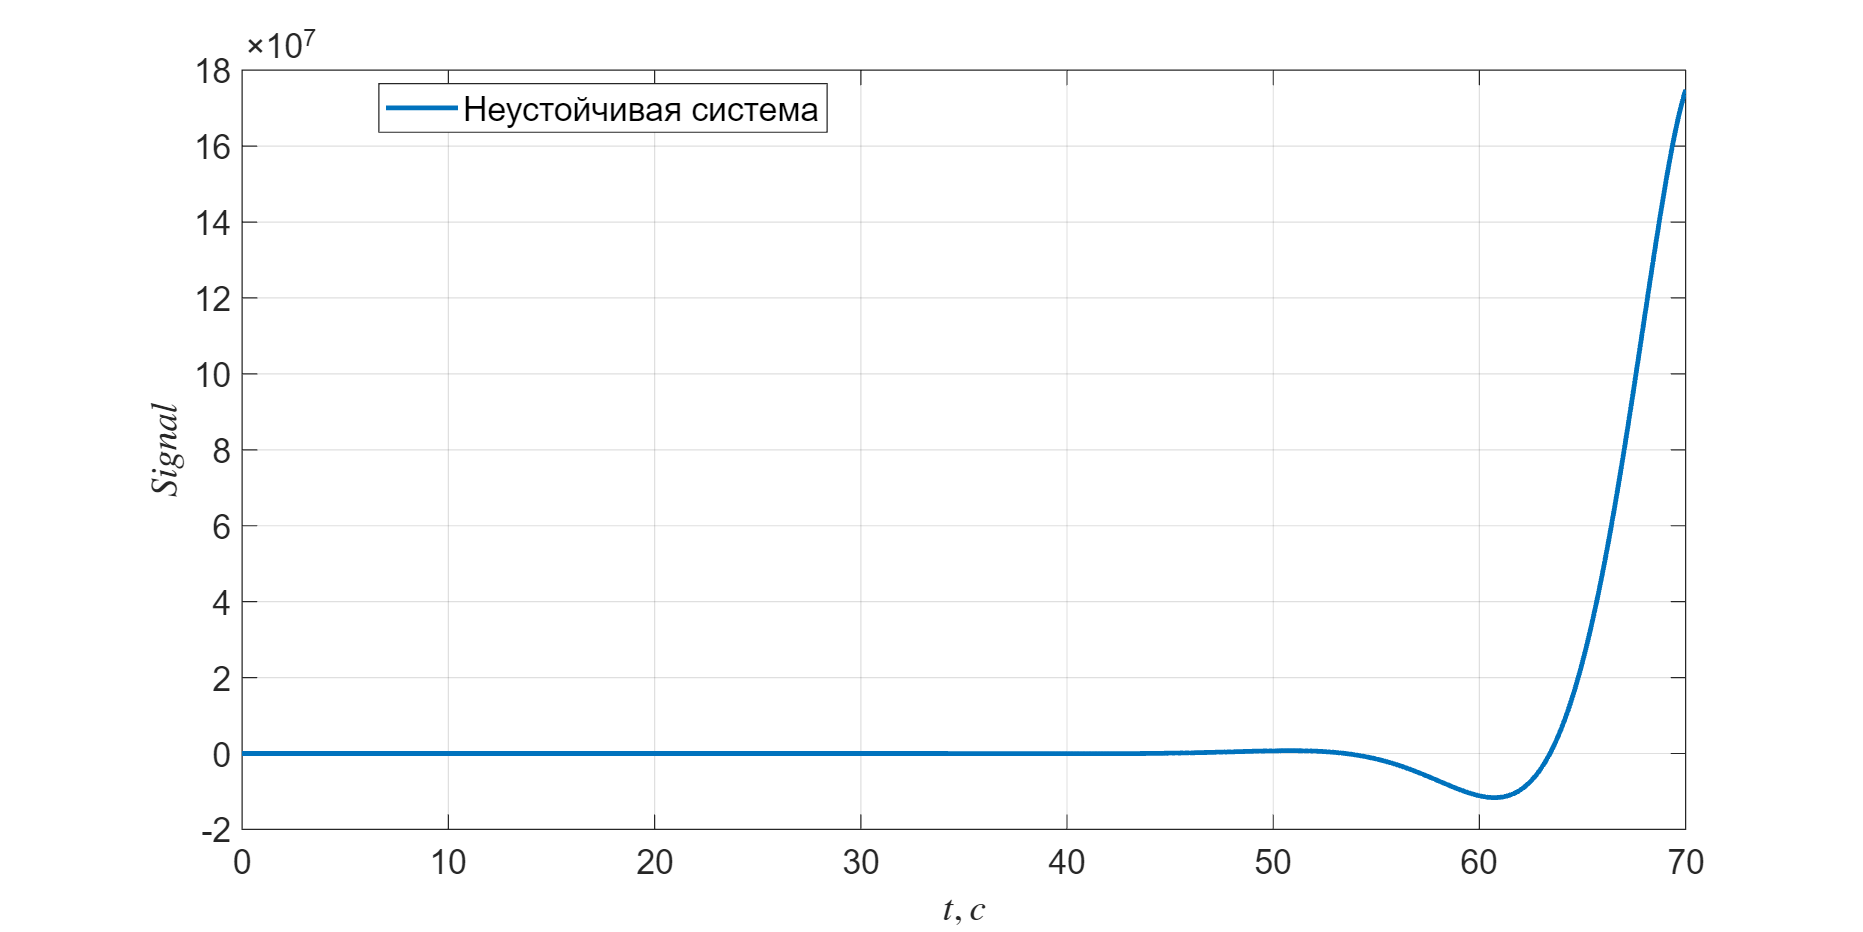

K_arr = [ 3, 0.7, -1 ];
T1_arr = [ 17, 2, -3 ];
T2_arr = [ 2/9, 5, 4 ];
type = ["Ассимптотически устойчивая система", "Система на границе устойчивости", "Неустойчивая система"];
simtime_arr = [ 500, 200, 70 ];
g = 1;

for k=1:3
    K = K_arr(k);
    T1 = T1_arr(k);
    T2 = T2_arr(k);
    simtime = simtime_arr(k);

    plot_1 = sim("lab_2_2.slx", simtime);
    plot(plot_1.y.Time, plot_1.y.Data, LineWidth=2, LineStyle="-", DisplayName=type(k));
    hold on;

    grid on;
    legend(Location="best", FontSize=14);
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$Signal$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_2_KT1T2_%d.png', k);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

function y = y_fm_1(t)
    y = 5.5 .* exp(-4.5 .* t) - 4.5 .* exp(-5.5 .* t);
end
function y = y_fm_2(t)
    y = exp(-3.7 .* t) .*(0.74 .* sin(5 .* t) + cos(5 .* t));
end
function y = y_fm_3(t)
    y = cos(29 .* t);
end
function y = y_fm_4(t)
    y = exp(0.7 .* t) .* (-0.007 .* sin(5 .* t) + 0.05 .* cos(5 .* t));
end
function y = y_fm_5(t)
    y = -0.225 .* exp(5.5 .* t) + 0.275 .* exp(4.5 .* t);
end
function y = y_fm_6(t)
    y = 1 ./ 56 .* exp(2.8 .* t) - 1 ./ 56 .* exp(-2.8 .* t);
end